# Cameras

We render the chess set scene through a camera with a lens . The output is the spectral irradiance at the sensor surface (the optical image).

This script  illustrates how to set the focal distance, and it reveals the depth of field for this double Gauss lens.

## Set up ISETCam

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the scene

thisR = piRecipeDefault('scene name','ChessSet');

Read 1 materials.
Read 1 textures.
***Scene parsed.


thisR.set('spatial resolution',512);

## Create a camera with a double Gauss lens

lensname    = 'dgauss.22deg.12.5mm.json';
doubleGauss = piCameraCreate('omni','lens file',lensname);

thisR.set('camera',doubleGauss);

The distance that will be in focus

thisR.set('focus distance',0.8);

Set the camera position a little higher than default.  That makes it easier to see the ruler on the chess board.

thisR.set('from',[0,0.18,-0.5]);

Rotate the camera down a bit.  The (x,y) axes for this scene surpise me.

piCameraRotate(thisR, 'x rot',-10);

Summarize the recipe information.  There is a lot for this scene.  But you can handle it.

thisR.summarize;


File information
-----------
Input:  /Users/wandell/Documents/MATLAB/iset3d/data/V3/ChessSet/ChessSet.pbrt
Output: /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt

Renderer information
-----------
Rays per pixel 32
Bounces 5

Camera parameters
-----------
Sub type: omni
Lens file name:   /Users/wandell/Documents/MATLAB/iset3d/data/lens/dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	0.80
Exposure time (s):	1.000000
Field of view (deg):	28.449267

Film parameters
-----------
subtype: image
x,y resolution: 512 512 (samples)
diagonal:   10 (mm)

Lookat parameters
-----------
from:	0.000 0.180 -0.500
to:	0.000 -0.102 0.466
up:	0.000 1.000 0.000
object distance: 1.006 (m)
                                                  material             positions (m)           sizes (m)     
                                            ____________________    ___________________

## Write and render

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet":"/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/renderings/ChessSet.dat /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt
*** Rendering time for ChessSet:  29.9 sec ***

  Reading image h=512 x w=512 x 31 spectral planes.


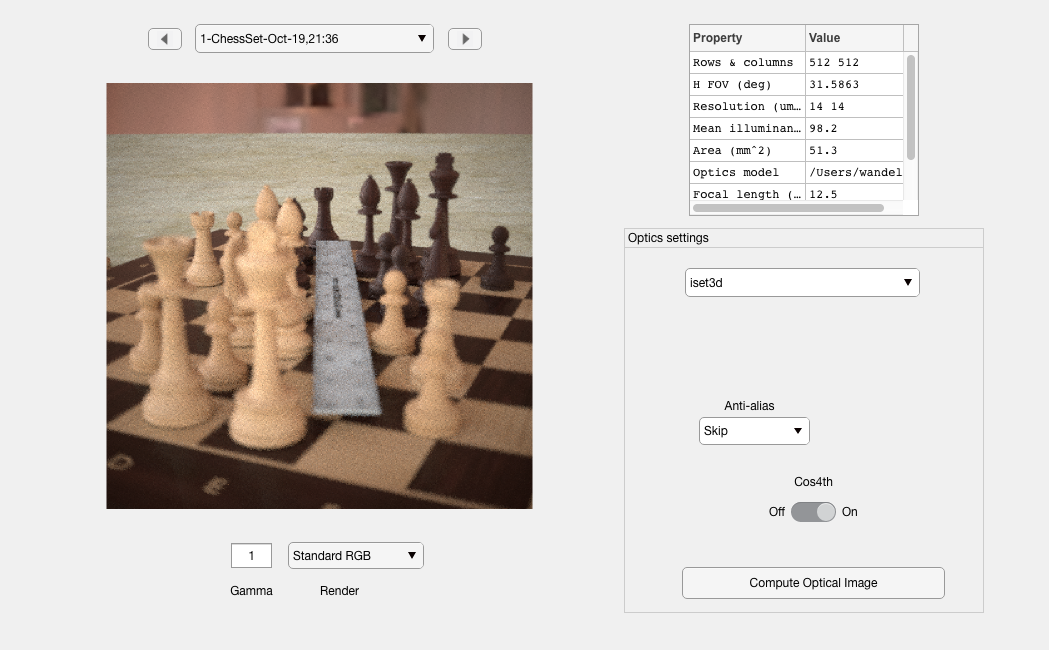

piWRS(thisR,'render type','radiance'); 

## Change the focus distance to 0.4m

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet":"/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/renderings/ChessSet.dat /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt
*** Rendering time for ChessSet:  29.6 sec ***

  Reading image h=512 x w=512 x 31 spectral planes.


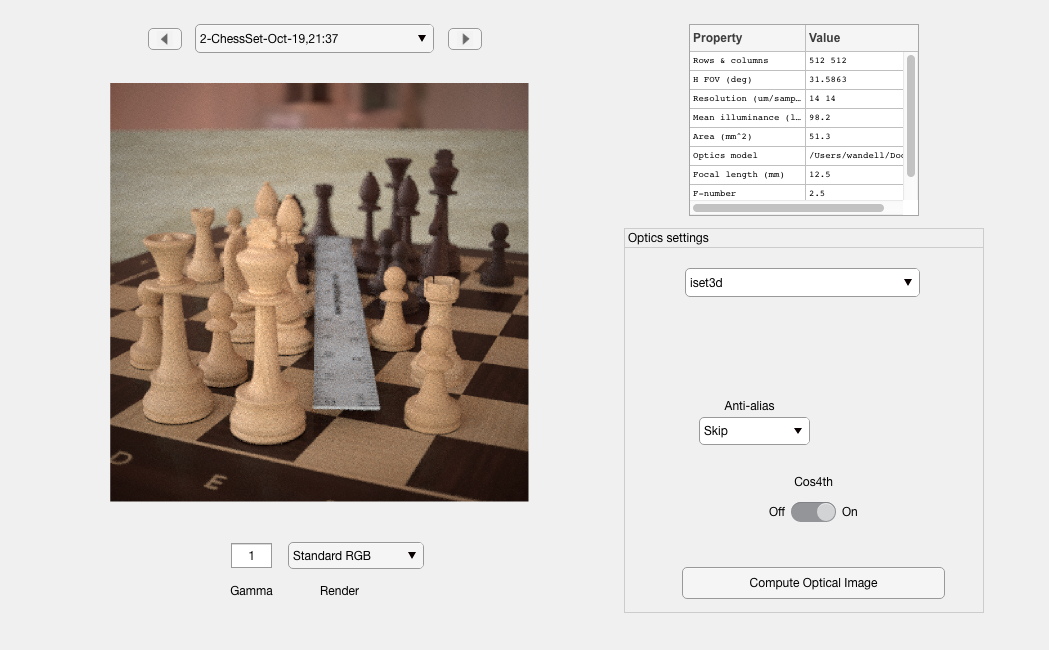

thisR.set('focus distance',0.4);
piWRS(thisR,'render type','radiance'); 